clc
clear all

% Connect to raspi
    robotPi = raspi('192.168.34.159', 'pi', 'raspberry');

% Create connection to the V2 Pi Camera
     robotCam = cameraboard(robotPi, 'Resolution', '1280x720');   


robotCam.ExposureMode = 'sports';
robotCam.AWBMode = 'fluorescent';

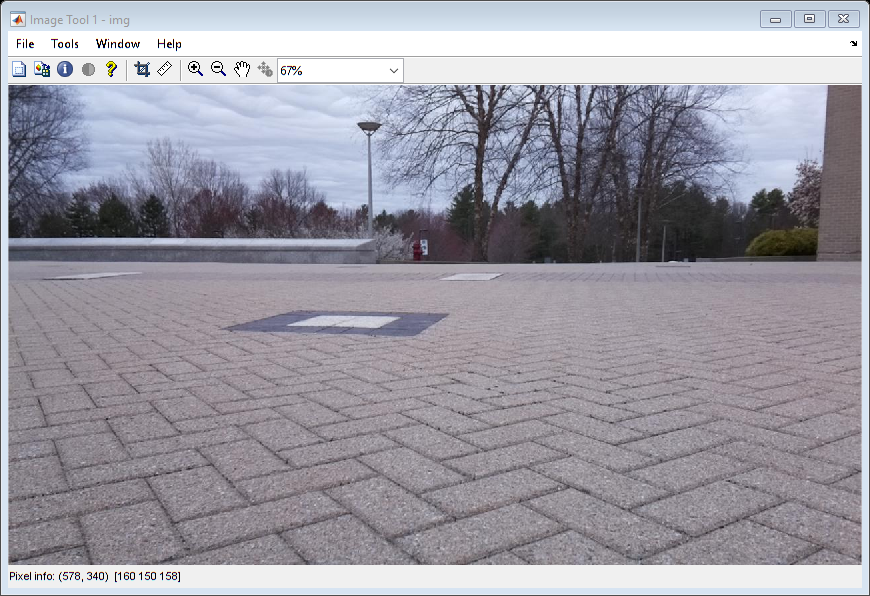


% Acquire a frame
img = snapshotCustom(robotCam);

% Display the frame in the imaqtool window
imtool(img);


clc
imaqreset


%create a free floating figure for images
% picamWindow = figure('name','Robot Pi Camera','NumberTitle','off','Visible','on');
% figure(picamWindow) % got to camWindow for imshow
% % imshow(img,'Border','tight')
% % Save file
% filename = input('filename:','s');
% saveas(gcf, filename)